# Examples for using the $\texttt{bisection\_method}$ function.

Copyright © 2021 Tamas Kis

### Example #1: Both roots of a quadratic function.

*Find the root(s) of *$f\left(x\right)=x^2 -1$*.*

Defining $f\left(x\right)$,

f = @(x) x^2-1;

We know $f\left(x\right)=x^2 -1$ has roots at $x=\pm 1$, but let's pretend we don't know this, and solve the problem using a more general approach. Since $f\left(x\right)$ is a quadratic function, we know that it will have either 0 roots (in the case where $f\left(x\right)$ does not cross the $x$-axis) or 2 roots. Let's assume the latter case (otherwise it would be pointless to try and find roots of $f\left(x\right)$). Therefore, we use the bisectrion method twice, with two different guesses for the interval containing the root. Let's pick $\left\lbrack -10,0\right\rbrack$ and $\left\lbrack 0,10\right\rbrack$ as our initial guesses for this interval.

% finds first root of f(x) using the bisection method
root1 = bisection_method(f,-10,0)

root1 = -1.0000

% finds second root of f(x) using the bisection method
root2 = bisection_method(f,0,10)

root2 = 1.0000

### Example #2: Root of a more complicated function.

*Find a root of *$g\left(x\right)=h\left(m\left(x\right)\right)$* where *$h\left(x\right)=5x^2 -4$* and *$\cosh{\sqrt{x}}$*. Additionally, plot the intermediate root estimates vs. iteration number.*

First, we need to define $g\left(x\right)$. We define $g\left(x\right)$ as the MATLAB function $\texttt{gx}$ at the bottom of this page under "gx Function for Example #2". To define $g\left(x\right)$ as an anonymous function, we assign it a function handle:

g = @(x) gx(x);

Due to the complexity of $g\left(x\right)$, we have no idea where its root(s) is/aer. Let's make the initial guess $\left\lbrack a,b\right\rbrack =\left\lbrack -5,5\right\rbrack$. Solving for the root with the bisection method,

root = bisection_method(g,-5,5)

root = -0.2150

To obtain the intermediate root estimates, we need to call $\texttt{bisection\_method}$ with the optional input $\texttt{'all'}$. We perform this function call directly in the $\texttt{plot}$ command.

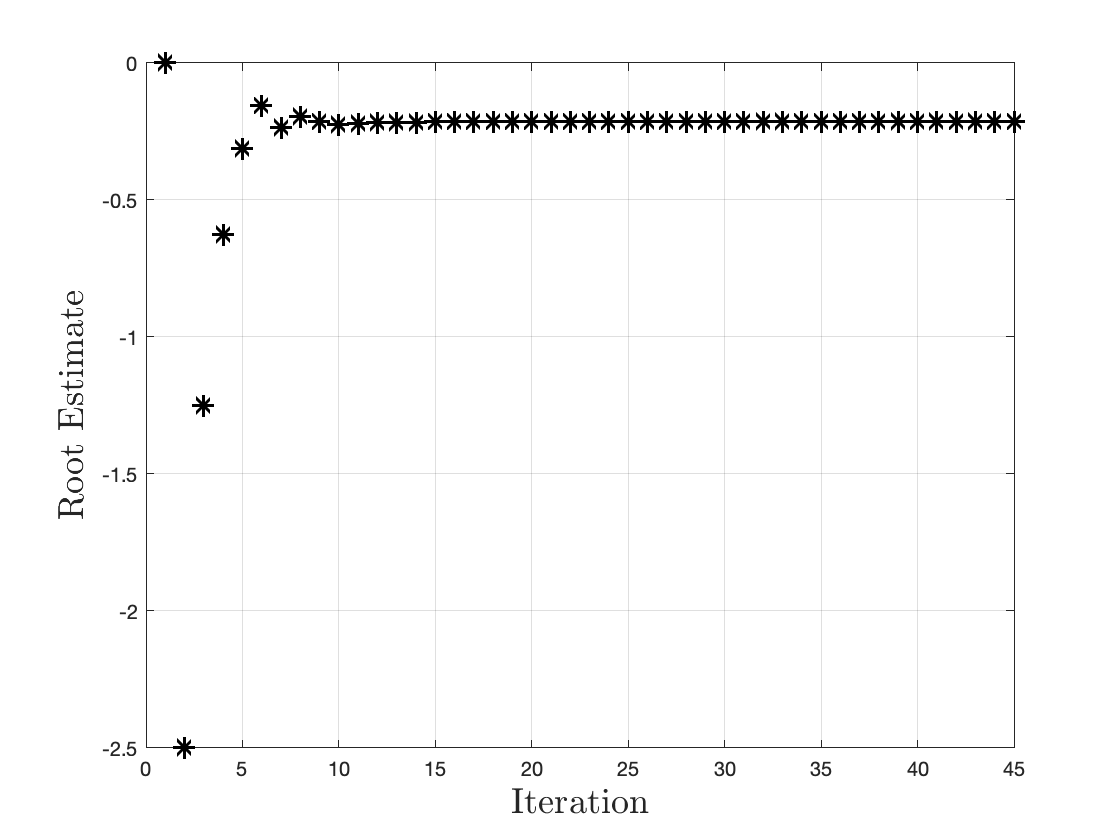

plot(bisection_method(g,-5,5,[],[],'all'),'k*','markersize',9,...
    'linewidth',1.5);
grid on;
xlabel('Iteration','interpreter','latex','fontsize',18);
ylabel('Root Estimate','interpreter','latex','fontsize',18);

### gx Function for Example #2

function g = gx(x)
    m = cosh(sqrt(x));
    h = 5*m^2-4;
    g = h;
end